close("all"); clear; clc;

A1 = [
    -1,-4;
    4,-1
    ];

b = 0.05;

ns = 100;
ts = 0.02;
tf = ns*ts;
t = linspace(0,tf,ns + 1);

X0 = zonotope2d(0.1.*eye(2),[1;0]);

R = girard2005Alg(X0,A1,b,t);

sys = ss(A1,eye(2),eye(2),0);
traj = @(x0)lsim(sys,repmat(0.*t,[2,1]),t,x0);
trajx = @(x0)traj(x0)*[1;0];
trajy = @(x0)traj(x0)*[0;1];
plotTraj = @(x0)plot(trajx(x0),trajy(x0),"k:", ...
    "LineWidth",2 ...
    );

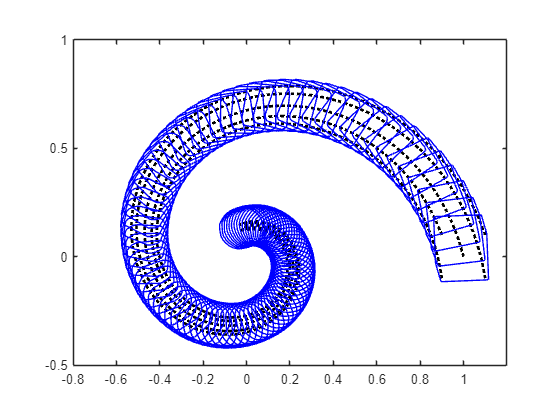

fig = figure();
axe = axes(fig);
% X0.plot();
hold(axe,"on");

x0 = [1,0;
    0.9,-0.1,;
    1.1,-0.1;
    0.9,0.1;
    1.1,0.1,
    ].';

cellfun(plotTraj,num2cell(x0,1));
hold(axe,"off");
arrayfun(@plot,R);
axis(axe,"equal");
box(axe,"on");
xlim([-0.8,1.2]);
ylim([-0.5,1]);

p = [
    -1 + 4i;
    -1 - 4i;
    -3 + 1i;
    -3 - 1i;
    -2
    ];

a = poly(p);

A = [[zeros(1,4);eye(4)],-fliplr(a(2:end)).'].';

n = size(A,1);

b = 0.01;

ns = 200;
ts = 0.005;
tf = ns*ts;
t = linspace(0,tf,ns + 1);

sys = ss(A,eye(n),eye(n),0);
traj = @(x0)lsim(sys,repmat(0.*t,[n,1]),t,x0);
fx = @(x)x(:,1);
fy = @(x)x(:,2);
plotTraj = @(x0)plot(fx(traj(x0)),fy(traj(x0)),"k:", ...
    "LineWidth",2 ...
    );

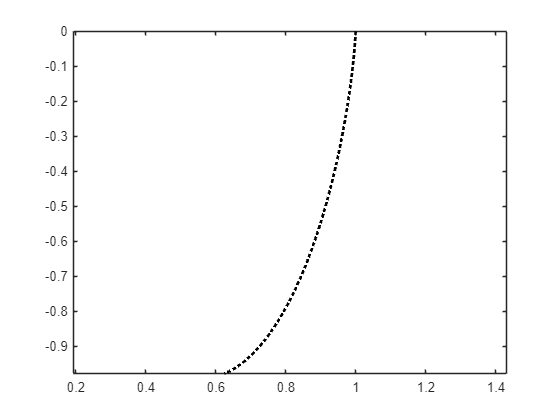

x0 = [1,0,0,0,0].';

fig = figure();
axe = axes(fig);
hold(axe,"on");
cellfun(plotTraj,num2cell(x0,1));
hold(axe,"off");
axis(axe,"equal");
box(axe,"on");